# How to use the `lib.SIRV_model `function.

The `lib.SIRV_model `is a function that collects and formats all the data for our model and then returns a `lib.class.DatedModelResult` object, which contains the results of our model.

## Setting up

To use these function, we must first ensure that all the date from our data-sources are present in our workspace. Normally, this will happen automatically when you start the project.

We'll need to have the following variables in our workspace:

- `cbs_AgeGroupPopulation`

- `rivm_cases`

- `rivm_reproduction`

If you don't see those variables in you workspace (in most cases, the right window next to this window), you should load them by double-clicking on the `Omrproject.prj` file or by running the script below:

scr.init % Loads the data from the API's into the workspace.

When you run this code for the first time, it might take a while before it starts, because it has to download the data from the API's of our datasources. It will then cache this data in the `./cache` folder of the project.

If you want to load the newest data from the API's or you encounter some errors because your cache isn't compatible anymore with the updated code, you can run the following code to reset all caches.

**Warning:** It can take a long while before all the data is downloaded (dependent on you internet connection.) You should therefore only run these scripts when it is nessicary.

if false% Check this checkbox if you want to reset and reload the workspace.
    scr.reset % Resets the caches
    scr.init % Reloads all the data from the API's.
end

Now all the data is loaded, so we are ready to use the `lib.SIRV_model`.

## Exploring functionality

Before we start explaining how the method actually works, let's just run it!

M = lib.SIRV_model

M =   DatedModelResult with properties:

          StartDate: 18-Nov-2020 14:36:53
               Date: [1×100 datetime]
              State: [1×100 lib.classes.ModelState]
             DeltaT: 1
             Method: EulerForward
                  n: 100
                  T: [1×100 duration]
                  N: [8×100 double]
                  S: [8×100 double]
                  I: [8×100 double]
                  R: [8×100 double]
                  U: [8×100 double]
                  V: [8×100 double]
              Alpha: [8×100 double]
                Tau: [8×100 double]
               Beta: [8×8×100 double]
                 Nu: [8×100 double]
                Rho: [8×100 double]
            SusVect: [8×100 double]
                  C: [8×8×100 double]
             P_CtoI: [8×8×100 double]
            ReprNum: [1×100 double]
            ReprEff: [1×100 double]
          SympRatio: [8×100 double]
    

The result should be an instance of `lib.models.DatedModelResult`. It just loaded and run the model with the standard configuration. You can get what these standard properties by just checking the properties of our new instance.

% The date from which the model starts. This is also the date for which the
% data was loaded.
M.StartDate

ans = datetime
   18-Nov-2020 14:36:53



% The initial values for this model.
M.State(1)

ans =   ModelState with properties:

     STD_Boundaries: [8×2 double]
        STD_SusVect: [8×1 double]
      STD_SympRatio: [8×1 double]
                  T: 0 days
                  S: [8×1 double]
                  I: [8×1 double]
                  R: [8×1 double]
              Alpha: [8×1 double]
               Beta: [8×8 double]
                 Nu: [8×1 double]
            SusVect: [8×1 double]
          SympRatio: [8×1 double]
                  N: [8×1 double]
                  V: [8×1 double]
                  U: [8×1 double]
                Tau: [8×1 double]
                Rho: [8×1 double]
                  C: [8×8 double]
             P_CtoI: [8×8 double]
            ReprNum: 0.9700
            ReprEff: 0.9400
         AsympRatio: [8×1 double]
             I_Symp: [8×1 double]
            I_Asymp: [8×1 double]
               StoI: [8×1 double]
               ItoR: [8×1 double]
               Sto


% The timestep used to run this model.
M.DeltaT

ans = 1


% The amount of timesteps for which the model is calculated.
M.n

ans = 100


% The numerical method used to calculate the values of the model.
M.Method

ans = categorical
     EulerForward 



% The names of the groups.
M.GroupName

ans = 8×1 string array
    "0-9"
    "10-19"
    "20-29"
    "30-39"
    "40-49"
    "50-59"
    "60-69"
    "70+"



% The total amount of people in each group
M.Population

ans =      1776480
     2001656
     2244283
     2143651
     2206345
     2531817
     2114088
     2396273


### Using the data

For every property, we have that the first dimension is the group index (if nesicary) and the last dimension the timestamp. Lets explore some examples of how we can get data directly from the class.

% Get the amount of succeptible people in group 1 for each timestep.
M.S(1,:)

ans = 	1.0e+06 *

    1.7716    1.7710    1.7704    1.7698    1.7692    1.7686    1.7680    1.7673    1.7667    1.7661    1.7654    1.7648    1.7641    1.7635    1.7628    1.7621    1.7615    1.7608    1.7602    1.7595    1.7589    1.7582    1.7576    1.7569    1.7563    1.7556    1.7550    1.7543    1.7537    1.7531    1.7524    1.7518    1.7512    1.7506    1.7499    1.7493    1.7487    1.7481    1.7475    1.7469    1.7463    1.7458    1.7452    1.7446    1.7440    1.7435    1.7429    1.7424    1.7418    1.7413



% Get the transmission matrix at the last timestep.
M.Beta(:,:,end)

ans =     0.0350    0.0030    0.0027    0.0082    0.0051    0.0028    0.0024    0.0017
    0.0037    0.0402    0.0033    0.0037    0.0077    0.0029    0.0006    0.0038
    0.0048    0.0044    0.0224    0.0214    0.0109    0.0100    0.0018    0.0038
    0.0183    0.0143    0.0170    0.0441    0.0318    0.0123    0.0086    0.0083
    0.0170    0.0105    0.0178    0.0199    0.0275    0.0127    0.0026    0.0056
    0.0023    0.0048    0.0192    0.0133    0.0151    0.0203    0.0093    0.0062
    0.0040    0.0026    0.0068    0.0111    0.0091    0.0147    0.0168    0.0164
    0.0033    0.0029    0.0040    0.0078    0.0130    0.0067    0.0060    0.0255



% Get the effective reproduction number.
M.ReprEff

ans =     0.9400    0.9393    0.9387    0.9380    0.9373    0.9367    0.9360    0.9354    0.9348    0.9341    0.9335    0.9329    0.9323    0.9317    0.9311    0.9305    0.9299    0.9293    0.9287    0.9281    0.9275    0.9270    0.9264    0.9258    0.9253    0.9247    0.9242    0.9237    0.9231    0.9226    0.9221    0.9216    0.9211    0.9205    0.9200    0.9195    0.9190    0.9186    0.9181    0.9176    0.9171    0.9167    0.9162    0.9157    0.9153    0.9148    0.9144    0.9139    0.9135    0.9131


You can then go wild on this variables and calculate everything that you need. For example:

% Get the total amount of people that moved from S to I.
sum(M.StoI, 2)

ans = 	1.0e+05 *

    0.4527
    0.5767
    0.9873
    1.7999
    1.2823
    1.1831
    0.8321
    0.7776


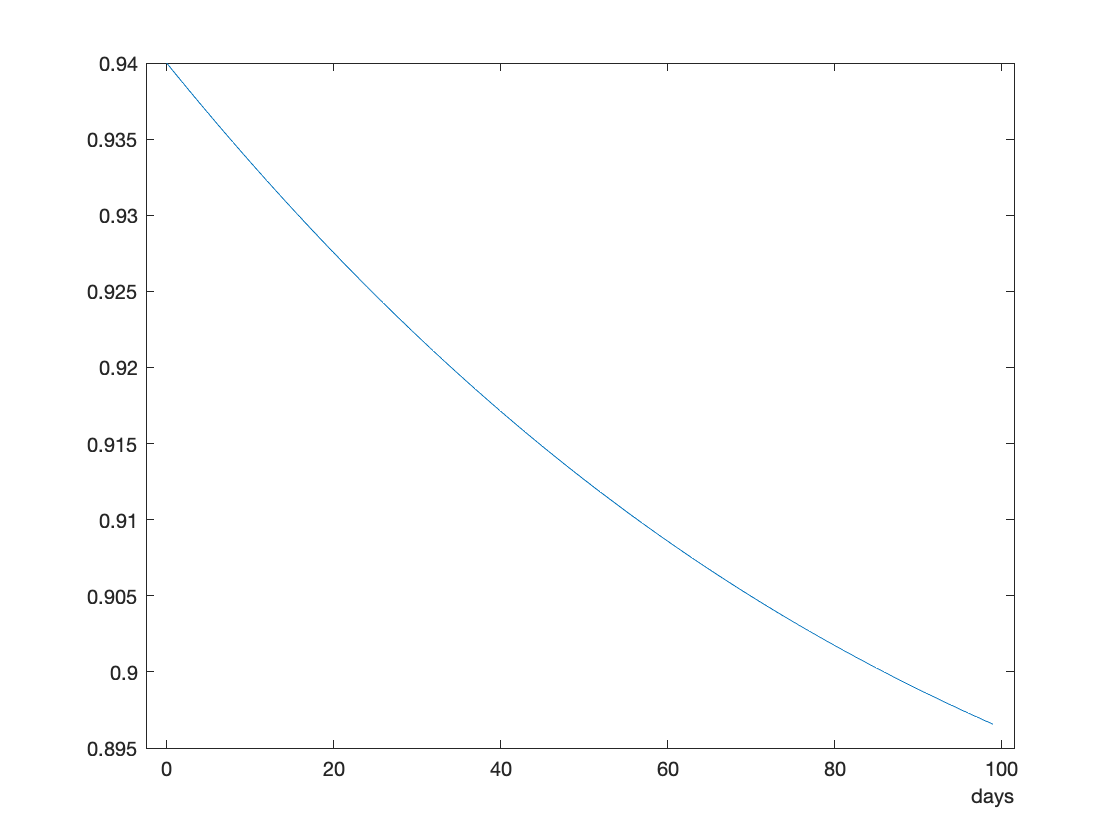


% Plot the effective reproduction number against time.
plot(M.T, M.ReprEff)

### Convert to tables

If you don't like working with object instances, you can easily convert the object to a table by the following command:

% Convert the `ModelResult` into a table with the format that you choose.
M.toTable( ...
    {'S', 'I', 'R', 'V', 'ReprNum'}, ... % The columns of the table. 
    'GroupSubTables', false, ... % Show groups in subtables.
    'TimeTable', true... % Create a MATLAB timetable instead of a normal table.
)

ans = 100×5 timetable
            Time                 S               I               R               V          ReprNum
    ____________________    ____________    ____________    ____________    ____________    _______

    18-Nov-2020 14:36:53    [1×8 double]    [1×8 double]    [1×8 double]    [1×8 double]    0.96996
    19-Nov-2020 14:36:53    [1×8 double]    [1×8 double]    [1×8 double]    [1×8 double]    0.96996
    20-Nov-2020 14:36:53    [1×8 double]    [1×8 double]    [1×8 double]    [1×8 double]    0.96996
    21-Nov-2020 14:36:53    [1×8 double]    [1×8 double]    [1×8 double]    [1×8 double]    0.96996
    22-Nov-2020 14:36:53    [1×8 double]    [1×8 double]    [1×8 double]    [1×8 double]

### Changing the size of the the result.

Imagine a situation where you want to plot the amount of vaccinated people in each group. From the previous sections, we know that we just have to do the following command:

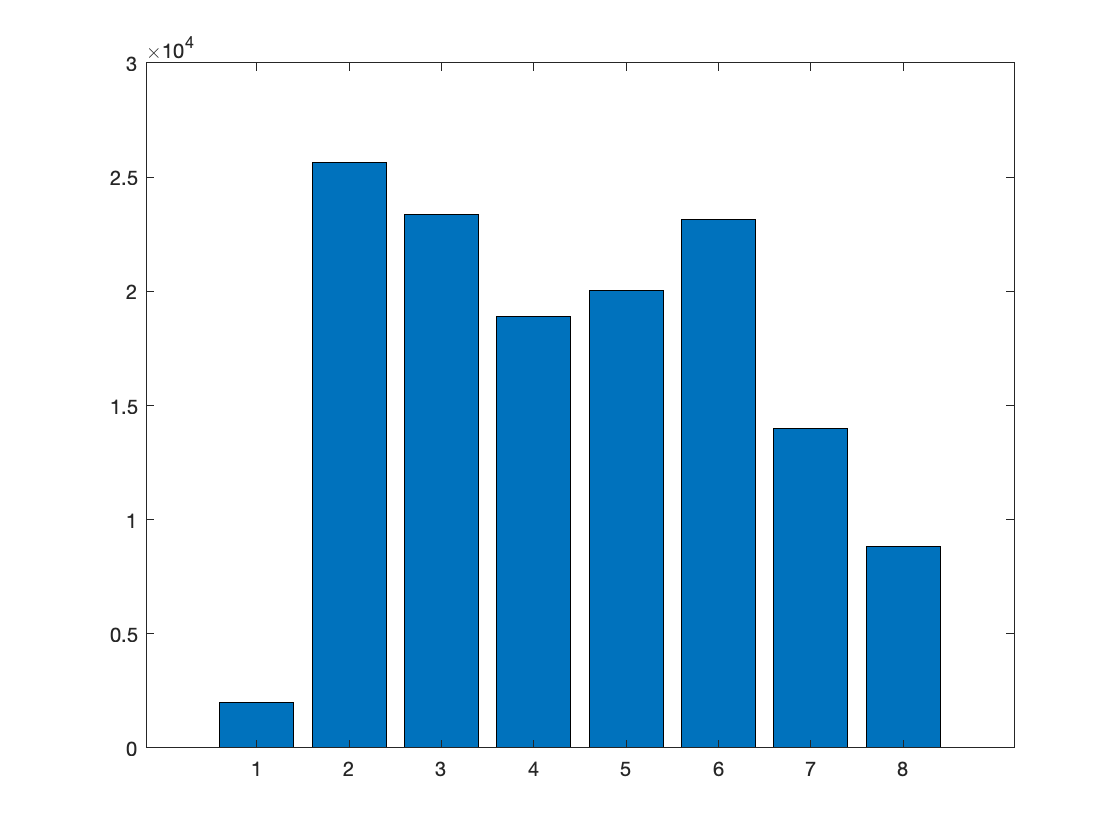

% Plot the total amount of infected people in each group on each date.
bar(M.State(1).I);

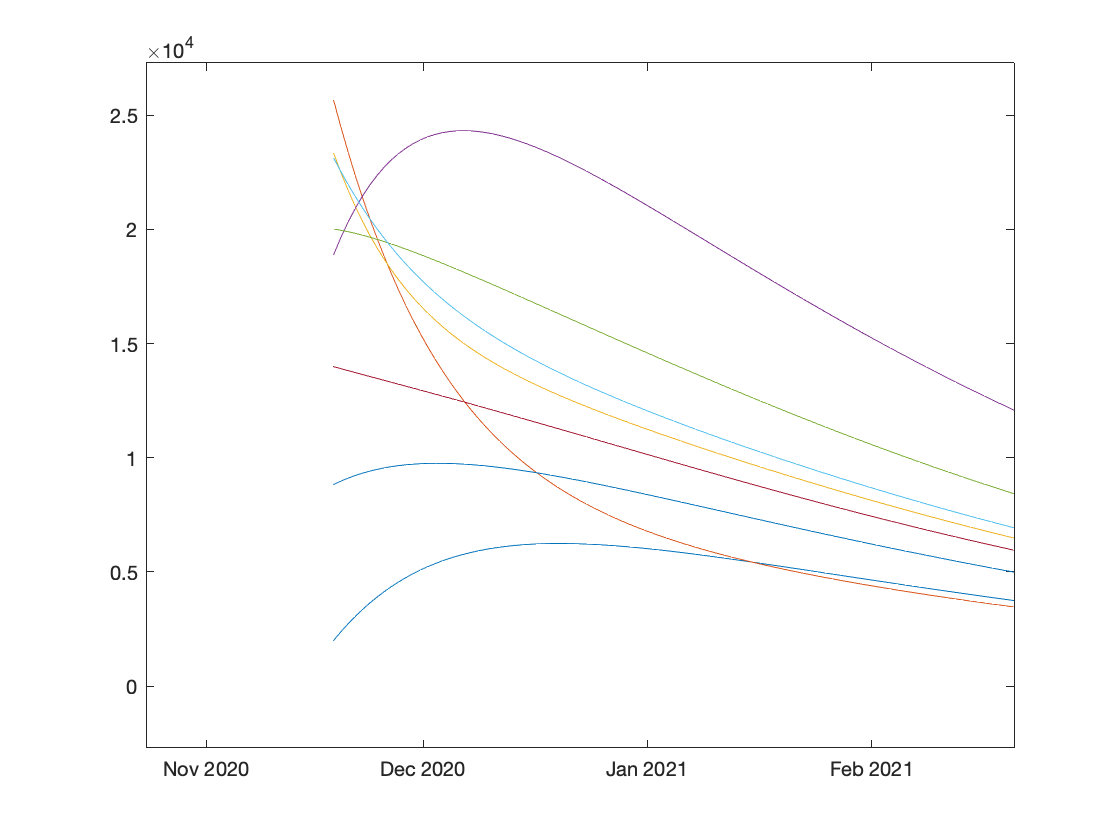

plot(M.Date, M.I)

Now maybe we want to see a bit more data. Instead of re-running the whole model, we can call the extend function to let the application run some extra steps for us!

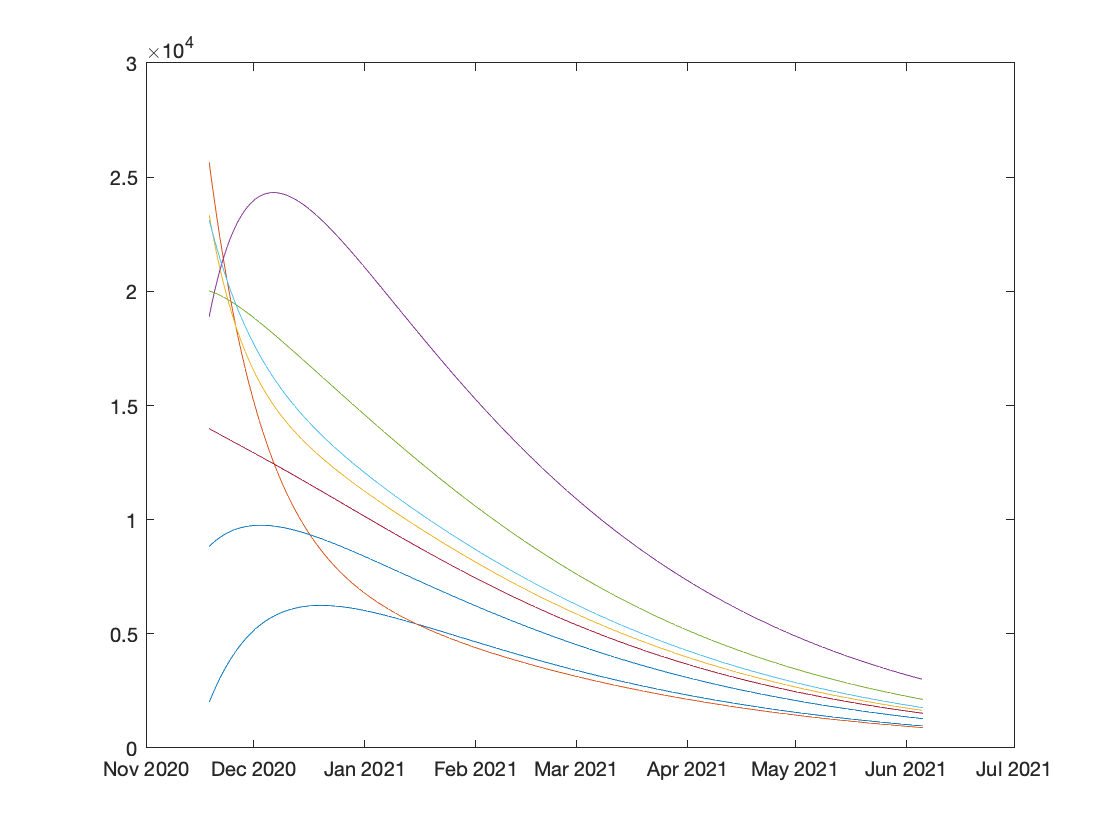

% Extend the result and plot the extended result.
M_extended = M.extend(100);
plot(M_extended.Date, M_extended.I)

We can also remove some of the datapoints with the `shrink `method.

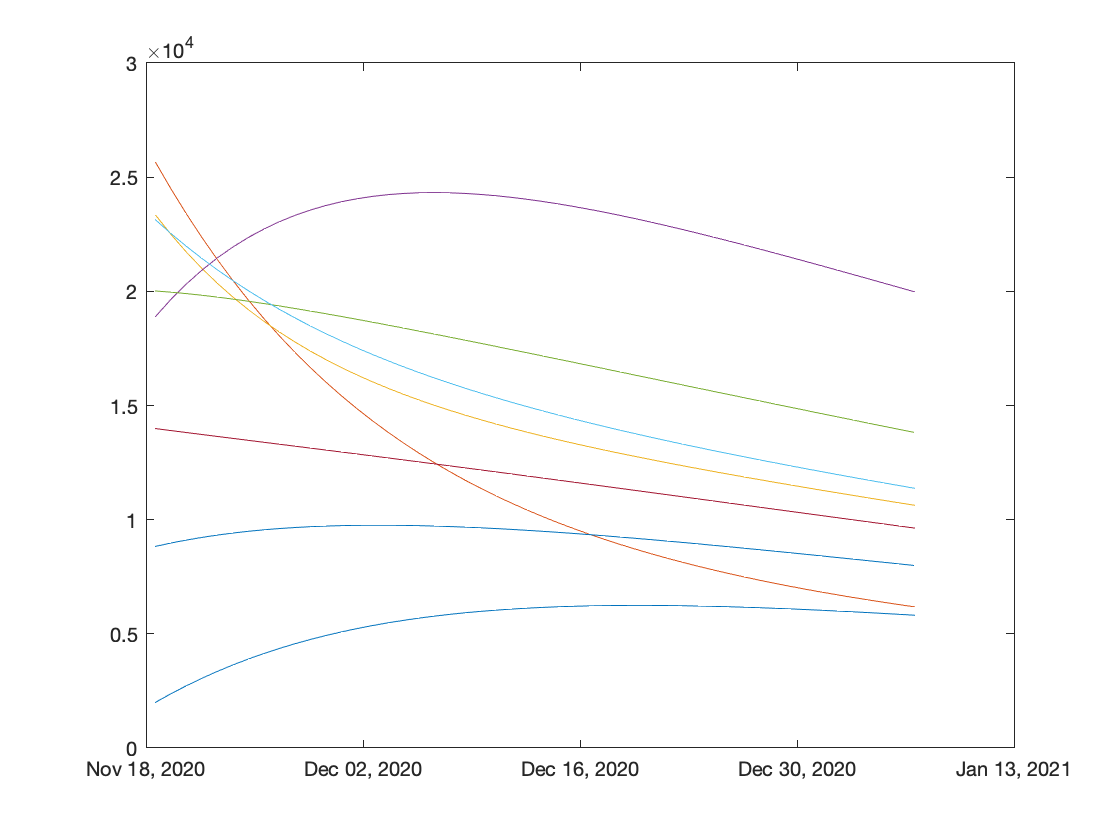

% Shrink the result by removing some datapoints.
M_shrinked = M.shrink(50);
plot(M_shrinked.Date, M_shrinked.I)

You can also just set the amount of datapoints that you want by setting the `n`-property on the `ModelResult`.

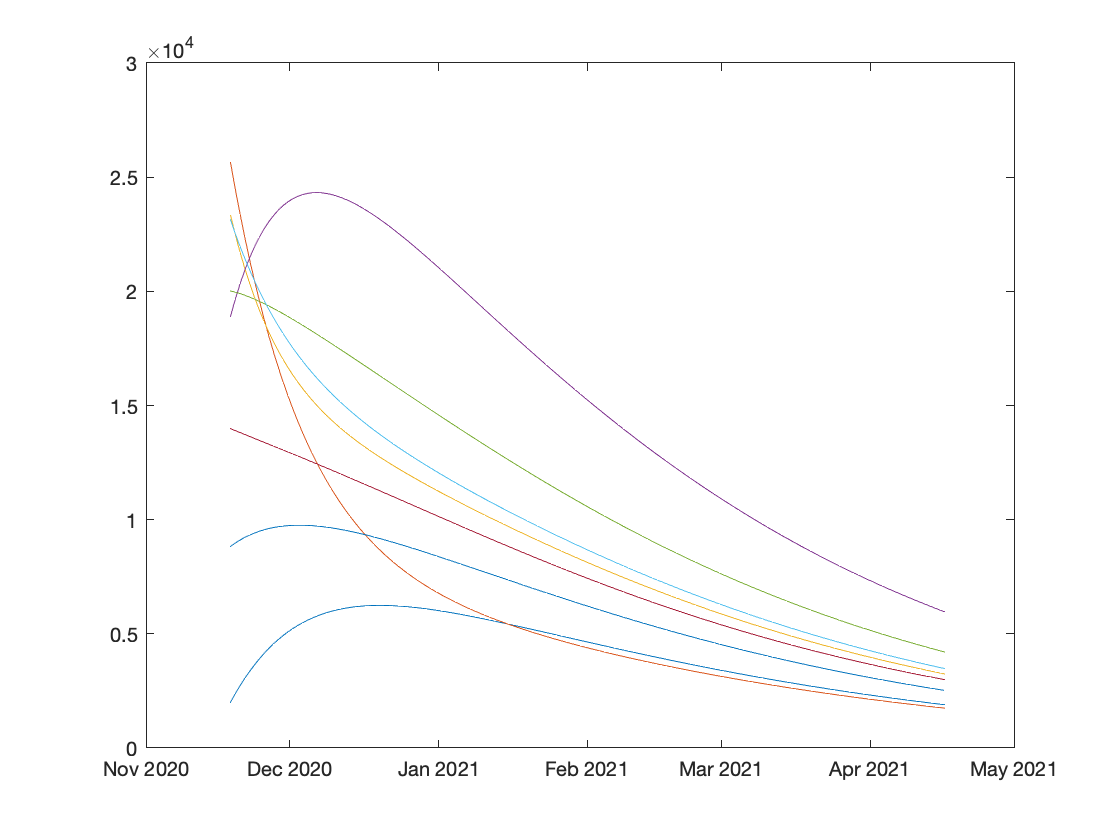

% Set the amount of datapoints that you want to use.
M.n = 150;
plot(M.Date, M.I)

## Initial Arguments

Now we know how to explore the the data on the model, let's see how we can change the way that the model runs.

We can change this by setting some input arguments for the` lib.SIRV_model `function. It accepts the following arguments:

- ($\Delta t$) The size of the steps in days. This is *always *the first argument of the application.

- An `OptionName` of an option for the model. In next section section we will discuss some of these options.

- The `OptionValue` of the option. Differs for every options.

- Another `OptionName`...

- Another `OptionValue`...

- ...

All the options that you'll set will override the default values computed from the data of the API's.

*Example:*

% Call the lib.SIRV_model.
M = lib.SIRV_model(1, ... The timestap DeltaT
    'StartDate', '2020-10-09', ... The date for which the data should be loaded.
    'Steps', 160 , ... The amount of steps to calculate beforehand.
    'Method', "EulerForward", ... The numeric method to solve the ODE of the model.
    'AgeGroups', 0:5:70, ... The way the age groups should be devided.
    'ContactMatrixFile', "Contact_matrix.csv", ... The file that contains the contact matrix.
    'Tau', 5, ... The average time of an infection.
    'ReprNum', 1.376 ... Set the reproduction number to a fixed value.
)

% Some data visualisation to see how the data changes.
table(M.N(:,1), round(M.S(:,1)), round(M.I(:,1)), round(M.R(:,1)), ...
    'RowNames', M.GroupName, ...
    'VariableNames', {'N', 'S', 'I', 'R'} ...
) % The groups and initial values.
plot(M.Date, M.I) % The Infectious people per timestep.

The order in which you set the options matter! Some options set the same values in the initail state. The latest option will be applied on the initial state that was set by an earlier option.

## Inserting Vaccination Strategies

You can run the model with a vaccination strategy, for example:

% Defining the strategy. Value ixj is the amount of people in age group
% i that you will vaccinate at DAY j.
Strat = [
    0 0 0 0 0 0 0 0 0 0 0 2 4 4 4 4 4 4 4 4 4 4 4 6 6 6 6 3 3 3 3 3 3 3 3 3
    5 5 5 5 5 5 5 5 5 5 5 3 1 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0
] * 1e5;

% Running the model.
M = lib.SIRV_model(0.1, ...
   'Steps', 400, ...
   'AgeGroups', [0,50;50,inf], ...
   'VaccinationStrategy', Strat ...
);

% Plot of the vaccinated people per age group.
plot(M.T, M.Nu)
plot(M.T, [M.V;M.U])